% MATLAB script to generate and plot a chirp signal

% Parameters
Fs = 1000;       % Sampling frequency (Hz)
T = 1;           % Duration (seconds)
t = 0:1/Fs:T;    % Time vector

% Single chirp
f0 = 10;         % Start frequency (Hz)
f1 = 200;        % End frequency (Hz)
chirp_signal = chirp(t, f0, T, f1, 'linear');

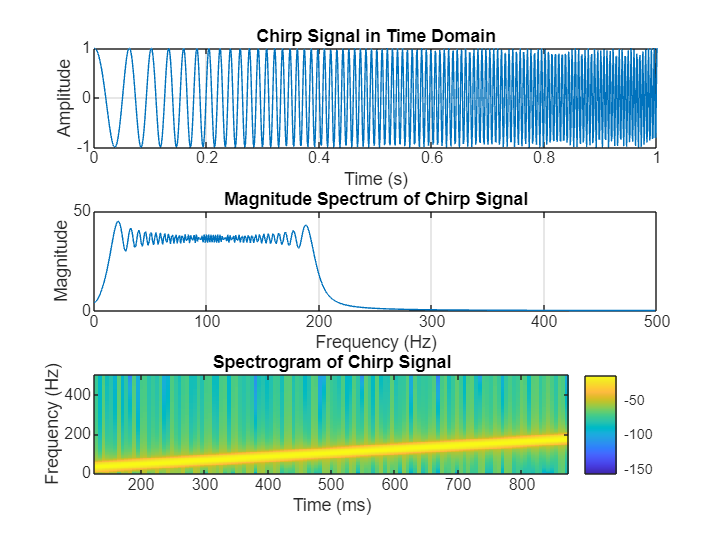

% Plot in Time Domain
figure;
subplot(3,1,1);
plot(t, chirp_signal);
title('Chirp Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Compute and plot Frequency Spectrum
Y = fft(chirp_signal); 
N = length(Y); 
f = (0:N-1)*(Fs/N);  % Frequency vector
half_N = floor(N/2);  % Ensure integer index

subplot(3,1,2);
plot(f(1:half_N), abs(Y(1:half_N))); % Plot single-sided spectrum
title('Magnitude Spectrum of Chirp Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Compute and plot Spectrogram
subplot(3,1,3);
spectrogram(chirp_signal, 256, 250, 256, Fs, 'yaxis');
title('Spectrogram of Chirp Signal');
colorbar;